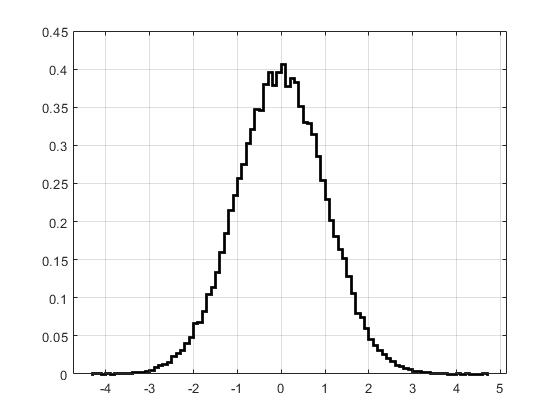

clear variables; close all;clc

% data generation
N = 50000;
x = 0;
P = 1;
data = randn(1,N)*P+x;

% pdf estimation
histogram(data,'Normalization','pdf','DisplayStyle','stairs','LineWidth',2,'EdgeColor','k'); grid on;

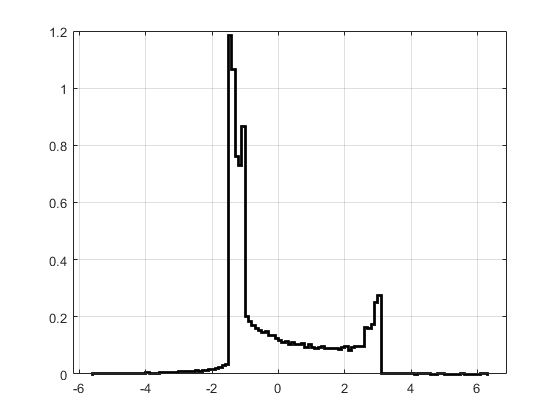

% non linear transformation
f = @(x) cos(4*(x/2 + 0.7)) - 1.3*x;
fdata = f(data);

% pdf estimation
histogram(fdata,'Normalization','pdf','DisplayStyle','stairs','LineWidth',2,'EdgeColor','k'); grid on;

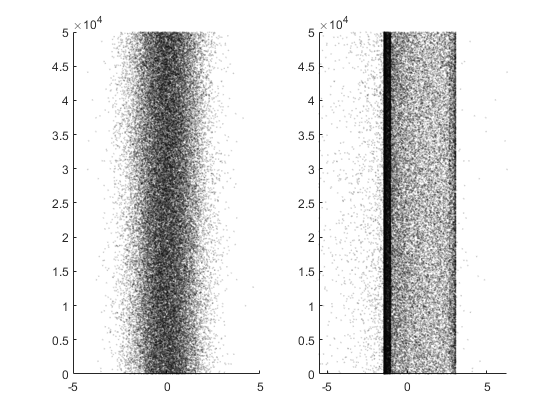

subplot(1,2,1)
scatter(data,1:N,1,'k','MarkerEdgeAlpha',0.1,'MarkerFaceAlpha',0.1);
subplot(1,2,2)
scatter(fdata,1:N,1,'k','MarkerEdgeAlpha',0.1,'MarkerFaceAlpha',0.1);

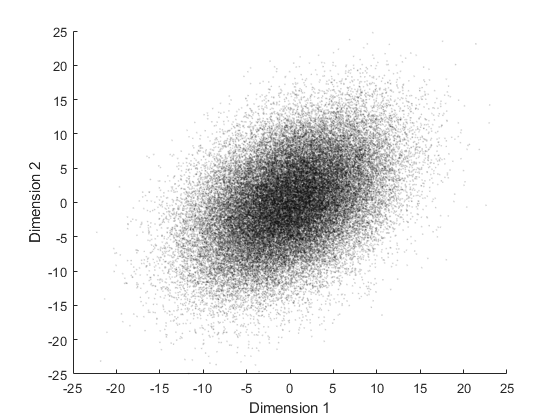

% multivariate example

% sampling random variables from multivariate gaussian distribution
x = [0, 0]';
P = [32 15;15 40];
data = mvnrnd(x,P,N);

% plot data
figure
scatter(data(:,1),data(:,2),1,'k','MarkerEdgeAlpha',0.1,'MarkerFaceAlpha',0.1);
xlabel('Dimension 1');
ylabel('Dimension 2');
xlim([-25 25]);
ylim([-25 25]);

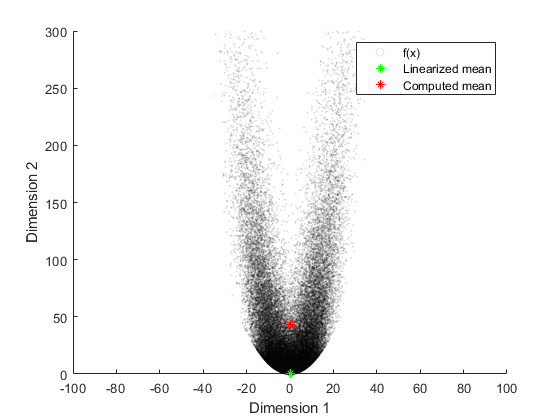

% non linear transformation
f = @(x) [x(:,1) + x(:,2), .1*x(:,1).^2 + x(:,2).^2];
fdata = f(data);

% linearized mean: extended kalman filter approach
mean_linear = f(x');

% computed mean: unscented kalman filter approach
mean_computed = mean(fdata);

% plot data
figure
scatter(fdata(:,1),fdata(:,2),1,'k','MarkerEdgeAlpha',0.1,'MarkerFaceAlpha',0.1);
hold on;
scatter(mean_linear(:,1),mean_linear(:,2),'*g')
scatter(mean_computed(:,1),mean_computed(:,2),'*r')
xlim([-100 100]);
ylim([0 300]);
xlabel('Dimension 1');
ylabel('Dimension 2');
legend('f(x)','Linearized mean','Computed mean');